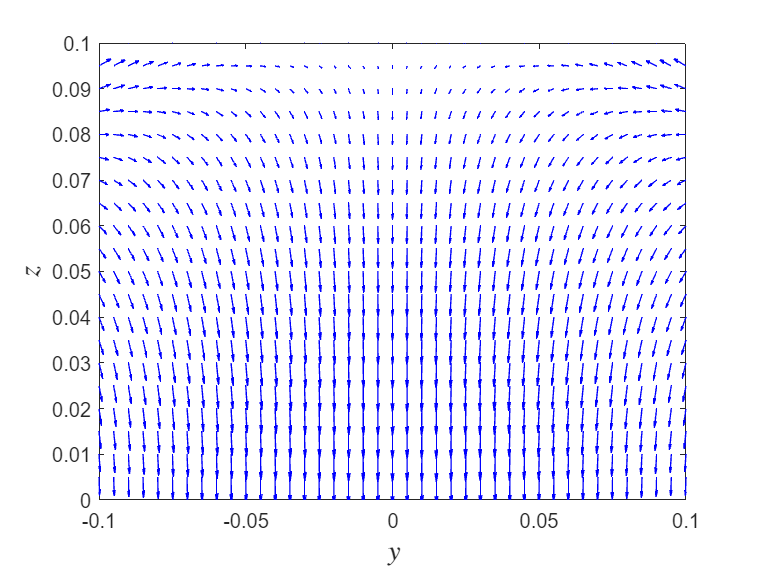

%% Gráfica del campo de desplazamientos
clear all;
% Datos del problema 
xOrg = 0; % Origen x-dir
yOrg = 0; % Origen y-dir
zOrg = 0; % Origen z-dir
L = 0.1; % Longitud en las direcciones y, z
g = 9.81; % Aceleración

% Constantes de elasticidad para el acero
%nu = 0.3; % Coeficiente de Poisson
%E = 210e9; % Módulo de Young [Pa]
%rho = 7850; % Densidad del material [kg/m^3]

% Aluminio
nu = 0.35; % Coeficiente de Poisson
E = 70e9; % Módulo de Young [Pa]
rho = 2699; % Densidad del material [kg/m^3]

% Genereación del mallado 2D
y = -L:0.005:L;
z = zOrg:0.005:L;
[Y, Z] = meshgrid(y, z);

% Cálculo del campo de desplazamientos en el plano YZ
vy = -(nu*rho*g/E)*Y.*Z; % Componente u del campo de desplazamientos
wz = (rho*g/(2*E))*[Z.^2 + nu*Y.^2 - L^2]; % Componente w del campo de desplazamientos para x = 0

% Gráfica del campo de desplazamientos
quiver(Y, Z, vy, wz, "Color", "b")
xlabel('$y$', 'Interpreter','latex', 'FontSize', 14)
ylabel('$z$', 'Interpreter', 'latex', 'FontSize', 14)
xlim([min(Y(:)) max(Y(:))]);
ylim([min(Z(:)) max(Z(:))]);


%saveas(gcf, "\\wsl.localhost\Ubuntu\home\marcoslm\Projects\University\2024-2\dmd\Tareas\T1\img\campo-desplazamientos", 'jpg')
